# Derivation of the Reference Strain and Boundary Condition

This code will establish a reference strain and boundary condition as in (Sec. III C)

We use Frenet convention, the $z$ direction is along the tangent, which is the derivative of $p$ with respect to $s$. Transfer $p^{\prime }$ to local frame using


$$R^T p^{\prime } =\left|p^{\prime } \right|e_z$$


where $e_z =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$

Since $\left|p^{\prime } \right|$ uses $s$ as the variable, $\left|p^{\prime } \right|=1$

From Eq. (6), $p^{\prime } =\textrm{Rv}$, therefore $R^T p^{\prime } =v=e_z ={\left\lbrack 0,0,1\right\rbrack }^T$ as long as $z$ is along the tangent of the curve, which is true for the original reference state. 

clc; clear
syms phi alpha s r theta rot_n
pi = sym(pi);
assume([phi alpha s r, theta],'real')
assume([phi alpha s r, theta],'positive')

$p^*$ is the reference postion vector

p_star = [ r*cos(-phi); r*sin(-phi); s*sin(-alpha); ]

$$p\_star = \left(\begin{array}{c} r\,\cos\left(\varphi \right)\\ -r\,\sin\left(\varphi \right)\\ -s\,\sin\left(\alpha \right) \end{array}\right)$$

p_star = subs(p_star, phi, s*cos(alpha)/r)

$$p\_star = \left(\begin{array}{c} r\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\\ -r\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\\ -s\,\sin\left(\alpha \right) \end{array}\right)$$


$$p^{*^{\prime } }$$


p_star_prime = diff(p_star, s)

$$p\_star\_prime = \left(\begin{array}{c} -\cos\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\\ -\cos\left(\alpha \right)\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\\ -\sin\left(\alpha \right) \end{array}\right)$$


$$R^*$$


R_star =  Rz(pi - phi)*Rx(-pi/2 - alpha)

$$R\_star = \left(\begin{array}{ccc} -\cos\left(\varphi \right) & -\cos\left(\alpha +\frac{\pi }{2}\right)\,\sin\left(\varphi \right) & -\sin\left(\varphi \right)\,\sin\left(\alpha +\frac{\pi }{2}\right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right)\,\cos\left(\alpha +\frac{\pi }{2}\right) & -\cos\left(\varphi \right)\,\sin\left(\alpha +\frac{\pi }{2}\right)\\ 0 & -\sin\left(\alpha +\frac{\pi }{2}\right) & \cos\left(\alpha +\frac{\pi }{2}\right) \end{array}\right)$$

A short demo of the trame transformation is shown in the following animaiton, In the beginning body frame $\textrm{xyz}$ coincides with global frame $\textrm{XYZ}$. We only look at the orientation. First,  rotate around $z$ axis $\pi -\phi \;$ degree, then roate around current $x$  axis $\frac{\pi }{2\;}-\alpha \;$

                           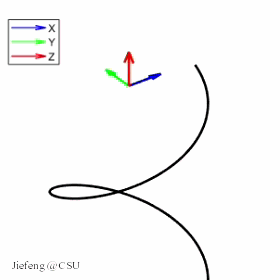

R_star = subs(R_star, phi,s*cos(alpha)/r);
R_star = simplify(R_star) % 

$$R\_star = \left(\begin{array}{ccc} -\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & \sin\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & -\cos\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\\ \sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & \cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\,\sin\left(\alpha \right) & -\cos\left(\alpha \right)\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\\ 0 & -\cos\left(\alpha \right) & -\sin\left(\alpha \right) \end{array}\right)$$


$$R^{*^{\prime } }$$


R_star_prime = diff(R_star, s) % derivative with respect to s

$$R\_star\_prime = \left(\begin{array}{ccc} \frac{\cos\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}{r} & \frac{\cos\left(\alpha \right)\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\,\sin\left(\alpha \right)}{r} & -\frac{{\cos\left(\alpha \right)}^{2}\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}{r}\\ \frac{\cos\left(\alpha \right)\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}{r} & -\frac{\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}{r} & \frac{{\cos\left(\alpha \right)}^{2}\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}{r}\\ 0 & 0 & 0 \end{array}\right)$$


$$R^{*T}$$


R_star_trans = R_star.'

$$R\_star\_trans = \left(\begin{array}{ccc} -\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & \sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & 0\\ \sin\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & \cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)\,\sin\left(\alpha \right) & -\cos\left(\alpha \right)\\ -\cos\left(\alpha \right)\,\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & -\cos\left(\alpha \right)\,\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right) & -\sin\left(\alpha \right) \end{array}\right)$$


$$\hat{u} =R^{*T} {R^* }^{\prime }$$


u_skew = R_star_trans*R_star_prime

$$u\_skew = \left(\begin{array}{ccc} 0 & -\frac{\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,{\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}}{r}-\frac{\cos\left(\alpha \right)\,{\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}\,\sin\left(\alpha \right)}{r} & \frac{{\cos\left(\alpha \right)}^{2}\,{\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}}{r}+\frac{{\cos\left(\alpha \right)}^{2}\,{\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}}{r}\\ \frac{\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,{\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}}{r}+\frac{\cos\left(\alpha \right)\,{\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}\,\sin\left(\alpha \right)}{r} & 0 & 0\\ -\frac{{\cos\left(\alpha \right)}^{2}\,{\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}}{r}-\frac{{\cos\left(\alpha \right)}^{2}\,{\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}}{r} & 0 & 0 \end{array}\right)$$

Simplify

u_skew = simplify(u_skew)

$$u\_skew = \left(\begin{array}{ccc} 0 & -\frac{\sin\left(2\,\alpha \right)}{2\,r} & -\frac{{\sin\left(\alpha \right)}^{2}-1}{r}\\ \frac{\sin\left(2\,\alpha \right)}{2\,r} & 0 & 0\\ \frac{{\sin\left(\alpha \right)}^{2}-1}{r} & 0 & 0 \end{array}\right)$$


$${\mathit{\mathbf{u}}}^*$$


u_star = simplify(unskew(u_skew), 'Steps',10)

$$u\_star = \left(\begin{array}{c} 0\\ \frac{{\cos\left(\alpha \right)}^{2}}{r}\\ \frac{\sin\left(2\,\alpha \right)}{2\,r} \end{array}\right)$$

Notice that the second element is  $\kappa^* =\frac{\cos^2 \left(\alpha \;\right)\;}{\;r}$ and the thrid element is $\tau^* =\frac{\sin \left(\alpha \;\right)\cos \left(\alpha \right)}{r}$


$$v^* =\left(R^* {\left.\right)}^T p^{\prime } \right.$$


 v_star = R_star_trans*p_star_prime 

$$v\_star = \left(\begin{array}{c} 0\\ \cos\left(\alpha \right)\,\sin\left(\alpha \right)-\cos\left(\alpha \right)\,{\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}\,\sin\left(\alpha \right)-\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,{\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}\\ {\sin\left(\alpha \right)}^{2}+{\cos\left(\alpha \right)}^{2}\,{\cos\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2}+{\cos\left(\alpha \right)}^{2}\,{\sin\left(\frac{s\,\cos\left(\alpha \right)}{r}\right)}^{2} \end{array}\right)$$


v_star = simplify(v_star, 'Steps',50)

$$v\_star = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

This is the $\xi {\;}^*$

xi =  simplify([u_star.', v_star.'])

$$xi = \left(\begin{array}{cccccc} 0 & \frac{{\cos\left(\alpha \right)}^{2}}{r} & \frac{\sin\left(2\,\alpha \right)}{2\,r} & 0 & 0 & 1 \end{array}\right)$$


$$p_{0\;}$$


 p_star_0 = subs(p_star, s, 0)

$$p\_star\_0 = \left(\begin{array}{c} r\\ 0\\ 0 \end{array}\right)$$


$$R_0$$


 R_ref_0 =  subs(R_star, s, 0)

$$R\_ref\_0 = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & \sin\left(\alpha \right) & -\cos\left(\alpha \right)\\ 0 & -\cos\left(\alpha \right) & -\sin\left(\alpha \right) \end{array}\right)$$